MODULO QUANTIZERS

%% --- Parameters ---
% The value at the client (encoder)
x = 10.73; 

% Side information at the server (decoder). Should be close to x.
y = 10.65; 

% MQ parameters
k = 20;         % Use log2(k) bits for the message
epsilon = 0.1;  % Spacing of the fine lattice

%% --- Check the Condition for Perfect Reconstruction ---
% This is the condition from Lemma 3.1
delta_prime = abs(x - y);
condition_lhs = k * epsilon;
condition_rhs = 2 * (epsilon + delta_prime);
condition_met = (condition_lhs >= condition_rhs);

%% --- Run the Quantizer ---
fprintf('--- Modulo Quantizer Demo ---\n');

--- Modulo Quantizer Demo ---


fprintf('Original Value (x):        %.4f\n', x);

Original Value (x):        10.7300


fprintf('Side Information (y):      %.4f\n', y);

Side Information (y):      10.6500


fprintf('Distance |x-y| (Δ''):        %.4f\n\n', delta_prime);

Distance |x-y| (Δ'):        0.0800




fprintf('Parameters:\n');

Parameters:


fprintf('  k = %d, epsilon = %.4f\n\n', k, epsilon);

  k = 20, epsilon = 0.1000




fprintf('Condition for perfect reconstruction (kε >= 2(ε+Δ'')):\n');

Condition for perfect reconstruction (kε >= 2(ε+Δ')):


fprintf('  %.2f >= %.2f  -->  %s\n\n', condition_lhs, condition_rhs, string(condition_met));

  2.00 >= 0.36  -->  true




% 1. ENCODE the value x
[w, tilde_z_val] = mq_encoder(x, epsilon, k);
fprintf('--- Encoder Side ---\n');

--- Encoder Side ---


fprintf('Unbiased Quantized Value (εž):  %.4f\n', tilde_z_val);

Unbiased Quantized Value (εž):  10.7000


fprintf('Compressed Message (w = ž mod k):  %d\n\n', w);

Compressed Message (w = ž mod k):  7




% 2. DECODE the message w using side information y
q_val = mq_decoder(w, y, epsilon, k);
fprintf('--- Decoder Side ---\n');

--- Decoder Side ---


fprintf('Reconstructed Value:             %.4f\n\n', q_val);

Reconstructed Value:             10.7000




%% --- Analyze the Error ---
encoder_error = abs(x - tilde_z_val);
decoder_error = abs(tilde_z_val - q_val);

fprintf('--- Error Analysis ---\n');

--- Error Analysis ---


fprintf('Encoder Quantization Error |x - εž|:  %.4f (should be < ε)\n', encoder_error);

Encoder Quantization Error |x - εž|:  0.0300 (should be < ε)


fprintf('Decoder Reconstruction Error |εž - Q(x,y)|: %.4f\n', decoder_error);

Decoder Reconstruction Error |εž - Q(x,y)|: 0.0000



if condition_met
    fprintf('\nNOTE: The condition was met, so the decoder error is zero.\n');
    fprintf('The decoder perfectly recovered the encoder''s quantized value.\n');
else
    fprintf('\nNOTE: The condition was NOT met. The decoder made an error.\n');
    fprintf('The side info ''y'' was too far from ''x'' for the given k and ε.\n');
end


NOTE: The condition was met, so the decoder error is zero.


The decoder perfectly recovered the encoder's quantized value.


ROTATED MODULO QUANTIZERS

%% Rotated Modulo Quantizer (RMQ) Implementation
% This script demonstrates the Rotated Modulo Quantizer (RMQ) from the
% paper "Wyner-Ziv Estimators for Distributed Mean Estimation with Side
% Information and Optimization".
%
% The RMQ quantizes a d-dimensional vector 'x' using side information 'y'
% available at the decoder. It works by:
% 1. Applying a random rotation R to both x and y. [cite: 1]
% 2. Applying a simple 1D Modulo Quantizer (MQ) to each coordinate of the
%    rotated vectors. [cite: 1]
% 3. The decoder reconstructs the rotated vector and applies the inverse
%    rotation to get the final estimate. [cite: 2]

%% --- Parameters ---
% Vector Dimension (must be a power of 2 for Hadamard matrix) [cite: 1]
d = 64; 

% The L2 distance bound between x and y. [cite: 1]
Delta = 0.5;

% Client's private vector (d x 1 column vector)
x_vec = rand(d, 1) * 10;

% Generate the error vector with a norm of Delta
error_vec = randn(d, 1);
error_vec = error_vec / norm(error_vec) * Delta;

% Server's side information vector. [cite: 1]
y_vec = x_vec + error_vec;

% --- Quantizer Parameters ---
% Parameters k and epsilon for the underlying 1D Modulo Quantizer.
% We calculate them based on Lemma 3.2. [cite: 1]

% MQ levels (determines the number of bits per dimension)
k = 16; % Uses log2(16) = 4 bits per dimension

% Trade-off parameter to control bias (must be in (0, Delta)) [cite: 1]
delta_tradeoff = 0.1; 

% Calculated parameters for the 1D MQ based on Lemma 3.2 [cite: 1]
Delta_prime = sqrt(6 * (Delta^2 / d) * log(Delta / delta_tradeoff));
epsilon = (2 * Delta_prime) / (k - 2);

%% --- Generate the Random Rotation Matrix R ---
% R = (1/sqrt(d)) * H * D, where H is Walsh-Hadamard and D is random
% diagonal. This uses public randomness. [cite: 1]
D = diag(sign(randn(d, 1)));
H = hadamard(d);
R = (1/sqrt(d)) * H * D;

%% --- Run the RMQ Quantizer ---
fprintf('--- Rotated Modulo Quantizer (RMQ) Demo ---\n');

--- Rotated Modulo Quantizer (RMQ) Demo ---


fprintf('Dimension (d): %d\n', d);

Dimension (d): 64


fprintf('L2 Distance ||x-y|| (Δ): %.4f\n\n', norm(x_vec - y_vec));

L2 Distance ||x-y|| (Δ): 0.5000




fprintf('Parameters for underlying 1D MQ (from Lemma 3.2):\n');

Parameters for underlying 1D MQ (from Lemma 3.2):


fprintf('  k = %d, ε = %.4f, Δ'' = %.4f\n\n', k, epsilon, Delta_prime);

  k = 16, ε = 0.0277, Δ' = 0.1942




% 1. ENCODER SIDE (Algorithm 4) [cite: 2]
% Rotate the input vector x
x_rotated = R * x_vec; % [cite: 2]

% Apply 1D MQ encoder to each coordinate of the rotated vector
w_vec = zeros(d, 1);
tilde_z_rotated = zeros(d, 1);
for i = 1:d
    [w_vec(i), tilde_z_rotated(i)] = mq_encoder(x_rotated(i), epsilon, k);
end

fprintf('--- Encoder Side ---\n');

--- Encoder Side ---


fprintf('Encoder sent a %d-element message vector ''w''.\n\n', d);

Encoder sent a 64-element message vector 'w'.




% 2. DECODER SIDE (Algorithm 5) [cite: 2]
% Rotate the side information vector y
y_rotated = R * y_vec; % [cite: 2]

% Apply 1D MQ decoder to each coordinate using rotated side info
q_rotated = zeros(d, 1);
for i = 1:d
    q_rotated(i) = mq_decoder(w_vec(i), y_rotated(i), epsilon, k);
end

% Apply inverse rotation to get the final estimate.
% For this R, the inverse is the transpose: R^-1 = R'
x_reconstructed = R' * q_rotated; % [cite: 2]

fprintf('--- Decoder Side ---\n');

--- Decoder Side ---


fprintf('Decoder received ''w'' and used side info ''y'' to reconstruct x.\n\n');

Decoder received 'w' and used side info 'y' to reconstruct x.




%% --- Analyze the Error ---
% Check if the 1D MQ reconstruction was successful in the rotated space.
% If |x_rot(i) - y_rot(i)| <= Delta_prime, then q_rot(i) should equal
% tilde_z_rot(i).
coord_recon_error = norm(tilde_z_rotated - q_rotated);

% Calculate the final end-to-end reconstruction error.
final_error = norm(x_vec - x_reconstructed);

fprintf('--- Error Analysis ---\n');

--- Error Analysis ---


fprintf('Coordinate reconstruction error in rotated space ||εž'' - Q''||: %.6f\n', coord_recon_error);

Coordinate reconstruction error in rotated space ||εž' - Q'||: 0.000000


if coord_recon_error < 1e-9
    fprintf('  -> The 1D decoder successfully recovered the encoder''s quantized value for all coordinates.\n');
else
    fprintf('  -> The 1D decoder failed for some coordinates because the condition was not met.\n');
end

  -> The 1D decoder successfully recovered the encoder's quantized value for all coordinates.


fprintf('Final End-to-End Error ||x - Q(x,y)||: %.6f\n\n', final_error);

Final End-to-End Error ||x - Q(x,y)||: 0.105614




fprintf('NOTE: The final error is non-zero due to the initial quantization at the encoder.\n');

NOTE: The final error is non-zero due to the initial quantization at the encoder.


fprintf('The rotation allows this error to be controlled even with only an L2-norm distance guarantee.\n');

The rotation allows this error to be controlled even with only an L2-norm distance guarantee.


Subsampled RMQ

%% Subsampled RMQ (Q_WZ) Implementation
% This script demonstrates the Subsampled RMQ, a communication-efficient
% Wyner-Ziv quantizer.
%
% It builds on the Full RMQ by randomly sampling a subset of coordinates
% to quantize and transmit, reducing the total number of bits required.
% The decoder uses side information to intelligently reconstruct the
% unsampled coordinates. [cite: 2]

%% --- Parameters for Subsampled RMQ ---

% Communication bit budget per client vector. This is the main constraint.
r = 128; % Total bits allowed, must be < d * log2(k)

% Number of clients (for parameter setting from Eq. 9)
n = 10;

%% --- Set Parameters based on Equations 9 & 10 ---

% log_k is set based on the number of clients 'n'
log_k = ceil(log2(2 + sqrt(12 * log(n))));
k_sub = 2^log_k;

% Number of coordinates to sample based on bit budget 'r'
num_sampled_coords = floor(r / log_k);
mu = num_sampled_coords / d; % The subsampling fraction mu

% Set MQ parameters for the i-th client (we simulate for one client)
% where Delta_i is the L2 distance bound.
Delta_i = Delta; % From the Full RMQ section
delta_sub = Delta_i / sqrt(n); %
Delta_prime_sub = sqrt(6 * (Delta_i^2 / d) * log(Delta_i / delta_sub)); %
epsilon_sub = (2 * Delta_prime_sub) / (k_sub - 2); %

%% --- Run the Subsampled RMQ Quantizer ---
fprintf('\n--- Subsampled RMQ (Wyner-Ziv) Demo ---\n');


--- Subsampled RMQ (Wyner-Ziv) Demo ---


fprintf('Communication Budget (r): %d bits\n', r);

Communication Budget (r): 128 bits


fprintf('Total Coordinates (d):    %d\n', d);

Total Coordinates (d):    64


fprintf('Coordinates to Sample:    %d (μ = %.2f)\n\n', num_sampled_coords, mu);

Coordinates to Sample:    42 (μ = 0.66)




fprintf('Parameters for underlying 1D MQ (from Eq. 9):\n');

Parameters for underlying 1D MQ (from Eq. 9):


fprintf('  k = %d, ε = %.4f, Δ'' = %.4f\n\n', k_sub, epsilon_sub, Delta_prime_sub);

  k = 8, ε = 0.0548, Δ' = 0.1643





% 1. ENCODER SIDE (Algorithm 6) [cite: 2]
% The same random rotation R from the RMQ part is used.
x_rotated_sub = R * x_vec;

% Sample a random subset of coordinates using public randomness [cite: 2]
S = randperm(d, num_sampled_coords);

% Apply 1D MQ only on the sampled coordinates
w_sub_vec = zeros(num_sampled_coords, 1);
for j = 1:num_sampled_coords
    coord_idx = S(j);
    [w_sub_vec(j), ~] = mq_encoder(x_rotated_sub(coord_idx), epsilon_sub, k_sub);
end

fprintf('--- Encoder Side ---\n');

--- Encoder Side ---


fprintf('Encoder sent a %d-element message vector ''w'' (total bits = %d).\n\n', ...
    num_sampled_coords, num_sampled_coords * log_k);

Encoder sent a 42-element message vector 'w' (total bits = 126).




% 2. DECODER SIDE (Algorithm 7) [cite: 2]
% Decoder knows S and R from public randomness.
y_rotated_sub = R * y_vec;

% Decode only the sampled coordinates
x_tilde_sampled = zeros(num_sampled_coords, 1);
for j = 1:num_sampled_coords
    coord_idx = S(j);
    x_tilde_sampled(j) = mq_decoder(w_sub_vec(j), y_rotated_sub(coord_idx), epsilon_sub, k_sub);
end

% Reconstruct the full rotated vector (x_hat_R)
% Step 3 from Algorithm 7
diff_vec = x_tilde_sampled - y_rotated_sub(S);
avg_diff = sum(diff_vec) / num_sampled_coords; % This is the (1/μ) * Σ(...) part simplified

% Create the final rotated estimate
x_hat_R = y_rotated_sub;
x_hat_R(S) = x_hat_R(S) + diff_vec; % Or more simply, x_hat_R(S) = x_tilde_sampled;
% The paper's formula is equivalent to centering the error.
% x_hat_R = (1/mu) * sum(x_tilde_sampled(i) - y_rotated_sub(S(i)))*e_i + y_rotated_sub
% A simpler interpretation is to fill in decoded values and use side info for the rest.
% The version from Alg. 7 is implemented here:
x_hat_R_decoded_diff = zeros(d, 1);
x_hat_R_decoded_diff(S) = x_tilde_sampled - y_rotated_sub(S);
x_hat_R = (1/mu) * x_hat_R_decoded_diff + y_rotated_sub;


% Step 4: Inverse rotation [cite: 2]
x_reconstructed_sub = R' * x_hat_R;

fprintf('--- Decoder Side ---\n');

--- Decoder Side ---


fprintf('Decoder received partial message and reconstructed the full vector.\n\n');

Decoder received partial message and reconstructed the full vector.




%% --- Analyze the Error for Subsampled RMQ ---
final_error_sub = norm(x_vec - x_reconstructed_sub);

fprintf('--- Error Analysis (Subsampled vs. Full) ---\n');

--- Error Analysis (Subsampled vs. Full) ---


fprintf('Full RMQ Error:         %.6f (used %d bits)\n', final_error, d*log2(16));

Full RMQ Error:         0.105614 (used 256 bits)


fprintf('Subsampled RMQ Error:   %.6f (used %d bits)\n\n', final_error_sub, r);

Subsampled RMQ Error:   0.422322 (used 128 bits)




fprintf('NOTE: The subsampled version has a higher error, which is the expected\n');

NOTE: The subsampled version has a higher error, which is the expected


fprintf('trade-off for using significantly fewer communication bits.\n');

trade-off for using significantly fewer communication bits.


VISUAL

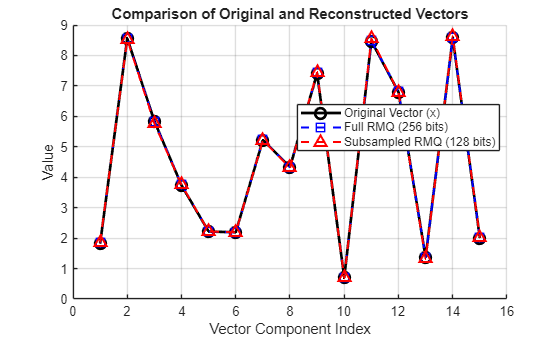

%% --- Visualization ---
% Plot the first few components of the vectors to visualize the results.

% Number of vector components to display in the plot
num_components_to_plot = 15;

% Create a figure
figure;
hold on;
grid on;

% Plot the original vector components
plot(1:num_components_to_plot, x_vec(1:num_components_to_plot), ...
    'k-o', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Original Vector (x)');

% Plot the reconstructed vector from Full RMQ
plot(1:num_components_to_plot, x_reconstructed(1:num_components_to_plot), ...
    'b--s', 'LineWidth', 1.5, 'MarkerSize', 8, 'DisplayName', sprintf('Full RMQ (%d bits)', d*log2(k)));

% Plot the reconstructed vector from Subsampled RMQ
plot(1:num_components_to_plot, x_reconstructed_sub(1:num_components_to_plot), ...
    'r--^', 'LineWidth', 1.5, 'MarkerSize', 8, 'DisplayName', sprintf('Subsampled RMQ (%d bits)', r));

% Add labels and title
title('Comparison of Original and Reconstructed Vectors');
xlabel('Vector Component Index');
ylabel('Value');
legend('show', 'Location', 'best');
xlim([0, num_components_to_plot + 1]);
hold off;

functions

function q_val = mq_decoder(w, y, epsilon, k)
% Implements the Modulo Quantizer (MQ) decoder from Algorithm 3.
%
% @param w          - The compressed integer message from the encoder.
% @param y          - The side information available at the decoder.
% @param epsilon    - The lattice spacing parameter.
% @param k          - The integer resolution parameter.
% @retval q_val     - The final reconstructed value.

    % Step 1: Compute z_hat by finding the closest candidate to the side info y
    % This solves the argmin problem: arg min |(z*k + w)*epsilon - y| over z in Z
    % which is equivalent to finding the integer z that is closest to:
    % (y/epsilon - w) / k
    z_hat = round((y / epsilon - w) / k);

    % Step 2: Reconstruct the integer index and output the final value
    tilde_z_reconstructed = z_hat * k + w;
    q_val = tilde_z_reconstructed * epsilon;
end

function [w, tilde_z_val] = mq_encoder(x, epsilon, k)
% Implements the Modulo Quantizer (MQ) encoder from Algorithm 2.
%
% @param x          - The input real number to be quantized.
% @param epsilon    - The lattice spacing parameter.
% @param k          - The integer resolution parameter for the modulo operation.
% @retval w         - The compressed integer message (tilde_z mod k).
% @retval tilde_z_val- The unbiased quantized value (epsilon * tilde_z).

    % Step 1: Compute the indices of the two nearest lattice points
    z_l = floor(x / epsilon);
    z_u = ceil(x / epsilon);

    % Step 2: Generate tilde_z through randomized unbiased quantization
    % The probability 'p' ensures that E[epsilon * tilde_z] = x
    if z_l == z_u
        tilde_z = z_l; % x is already on a lattice point
    else
        p = (x / epsilon) - z_l;
        if rand < p
            tilde_z = z_u;
        else
            tilde_z = z_l;
        end
    end
    
    % This is the high-resolution quantized value at the encoder
    tilde_z_val = epsilon * tilde_z;

    % Step 3: Output the compressed message using the modulo operation
    w = mod(tilde_z, k);
end